# Ajuste de iluminación

La iluminación de una imagen está dada por la forma en la que el foco o fuente de energía están localizados. La iluminación debe de ser uniforme en toda la imagen para que todas las regiones se vean con la misma cantidad de brillo y que no se noten cambios de nivel de gris por sombras generadas de manera aleatoria.

En procesamiento de imágenes médicas, este aspecto es fundamental, ya que una mala iluminación puede ocultar estructuras relevantes o resaltar de manera incorrecta zonas que no presentan interés clínico. Por ejemplo, una iluminación irregular puede provocar que tejidos blandos parezcan más oscuros o que ciertas regiones óseas aparezcan con un nivel de brillo mayor al real, afectando la interpretación diagnóstica.

El ajuste de iluminación busca compensar estas variaciones, ya sea mediante técnicas de preprocesamiento que normalizan la intensidad de los píxeles, o a través del control físico de la fuente de luz durante la captura. Entre los métodos computacionales más utilizados se encuentran la ecualización del histograma, la corrección de fondo y las transformaciones de intensidad que ajustan la gama dinámica de la imagen.

En resumen, asegurar una iluminación homogénea no solo mejora la calidad visual de la imagen, sino que también garantiza que los análisis posteriores —como segmentación, filtrado o detección de bordes— se realicen sobre datos más confiables y representativos de la realidad anatómica.

La intensidad capturada en cada píxel puede escribirse como:  


$$f(x,y) = i(x,y) \cdot r(x,y)$$


donde:  

- $f(x,y)$ es la imagen observada en las coordenadas espaciales $(x,y)$.  

- $i(x,y)$ representa la **componente de iluminación**, asociada a la cantidad de energía que llega a cada punto de la escena.  

- $r(x,y)$ corresponde a la **reflectancia** de la superficie, es decir, la proporción de luz reflejada por los objetos.  

En este modelo, la iluminación $i(x,y)$ suele variar lentamente en la imagen, mientras que la reflectancia $r(x,y)$ contiene los cambios bruscos asociados a bordes, texturas o estructuras anatómicas.  

Así, la tarea de **ajuste de iluminación** consiste en minimizar el efecto de $i(x,y)$ para resaltar la información estructural de $r(x,y)$, de modo que la imagen procesada tenga una distribución de brillo más uniforme y represente mejor los detalles importantes.

X = imread("/home/erit/Desktop/Imagenes/misc/5.1.11.tiff");
disp(['Dimensiones: ' num2str(size(X))]);

Dimensiones: 256  256


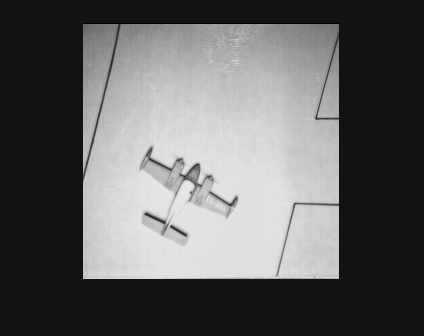

figure();
imshow(X);

X = double(X);
if length(size(X))>2
    X = mean(X,3);
end

Xnorm = reshape(normalize(X(:),"range"),size(X));
disp(['mínimo: ' num2str(min(Xnorm(:)))]);

mínimo: 0


disp(['máximo: ' num2str(max(Xnorm(:)))]);

máximo: 1


En muchos casos, la iluminación no es uniforme en la imagen, sino que presenta variaciones sistemáticas a lo largo de la posición de los píxeles. Una manera de modelar este fenómeno es suponer que la componente de iluminación $i(x,y)$ puede aproximarse mediante una función polinómica en las coordenadas espaciales $x$ y $y$.  

Un modelo de tercer grado permite capturar variaciones suaves pero complejas en la iluminación y puede expresarse como:  


$$i(x,y) = a_0 + a_1x + a_2y + a_3x^2 + a_4xy + a_5y^2 + a_6x^3 + a_7x^2y + a_8xy^2 + a_9y^3$$


donde los coeficientes $a_0, a_1, \ldots, a_9$ definen la forma de la función de iluminación.  El ajuste de los coeficientes polinómicos puede hacerse mediante técnicas de regresión a partir de la intensidad de los píxeles, de modo que se estima la iluminación global y posteriormente se aplica una corrección al dividir o restar $i(x,y)$ de la imagen original.  

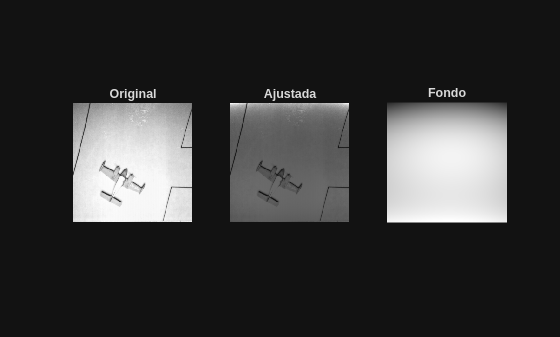

[X_bck,background] = background_adjst(X,'poly');

figure()
subplot(131)
imshow(Xnorm)
title("Original")

subplot(132)
imshow(X_bck)
title("Ajustada")

subplot(133)
imshow(background)
title("Fondo");

# Suavizado para obtener fondo

En algunos casos, debido a la forma o complejidad de la imagen, la estimación polinómica del fondo no arroja valores adecuados. Como alternativa, la estimación del fondo puede obtenerse mediante un proceso de suavizado, en el cual las variaciones locales rápidas se atenúan y se preservan únicamente los cambios de baja frecuencia. De esta forma, el resultado obtenido corresponde a una aproximación de la iluminación global o fondo de la imagen, eliminando los detalles finos y resaltando la tendencia general de intensidad.

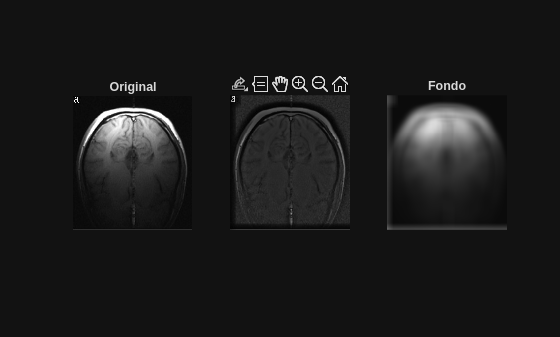

X = imread("/home/erit/Desktop/Imagenes/campo_1a.jpg");
X = double(X);
if length(size(X))>2
    X = mean(X,3);
end

Xnorm = reshape(normalize(X(:),"range"),size(X));

%[X_bck,background] = background_adjst(X,'poly',2);
[X_bck,background] = background_adjst(X,'gauss',25);

figure()
subplot(131)
imshow(Xnorm)
title("Original")

subplot(132)
imshow(X_bck)
title("Ajustada")

subplot(133)
imshow(background)
title("Fondo");

# DICOM

El formato **DICOM** (Digital Imaging and Communications in Medicine) es un estándar internacional diseñado para garantizar la interoperabilidad en el manejo de imágenes médicas. No solo almacena la información visual adquirida por modalidades como radiografía, tomografía o resonancia, sino también un conjunto amplio de metadatos que incluyen datos del paciente, detalles del estudio, parámetros de adquisición y del equipo utilizado.

Su mayor utilidad radica en la integración con sistemas hospitalarios como los **PACS** (Picture Archiving and Communication System), que permiten el almacenamiento y consulta de imágenes médicas; los **HIS** (Hospital Information System), que gestionan la información administrativa y clínica de los pacientes; y los **RIS** (Radiology Information System), especializados en la gestión de estudios radiológicos.

Gracias al estándar DICOM, distintos equipos y sistemas de fabricantes diversos pueden comunicarse entre sí dentro de un hospital, permitiendo que las imágenes y la información asociada fluyan de manera eficiente entre áreas de diagnóstico, archivo, consulta y análisis clínico.

filepath = "/home/erit/Desktop/Imagenes/dicom_chest/E1154S7I.dcm"

filepath = "/home/erit/Desktop/Imagenes/dicom_chest/E1154S7I.dcm"


X = dicomread(filepath);
    
% Leer la información asociada
info = dicominfo(filepath);

disp(['Imagen DICOM - ', info.PatientName.FamilyName]);

Imagen DICOM - 



% Mostrar metadatos relevantes
disp('--- Metadatos del archivo DICOM ---');

--- Metadatos del archivo DICOM ---


disp(['Paciente: ', info.PatientName.FamilyName, ', ', info.PatientName.GivenName]);

Paciente: , 


disp(['ID del paciente: ', info.PatientID]);

ID del paciente: 


disp(['Fecha de estudio: ', info.StudyDate]);

Fecha de estudio: 


disp(['Hora de estudio: ', info.StudyTime]);

Hora de estudio: 


disp(['Modalidad: ', info.Modality]);

Modalidad: MR


disp(['Fabricante: ', info.Manufacturer]);

Fabricante: 


disp(['Dimensiones de la imagen: ', num2str(size(X))]);

Dimensiones de la imagen: 512  512    1   76


disp(['Número de bits por píxel: ', num2str(info.BitsAllocated)]);

Número de bits por píxel: 16


## Stack

Un **stack** se refiere a un conjunto de imágenes bidimensionales adquiridas en secuencia y organizadas de manera que representan cortes consecutivos de un mismo volumen anatómico. Cada imagen del stack corresponde a un **slice** o plano específico, y al visualizar todas las imágenes en conjunto se puede reconstruir o examinar la estructura tridimensional del órgano o región de interés. Este concepto es fundamental en modalidades como **tomografía computarizada (CT)** o **resonancia magnética (MRI)**, donde la información volumétrica se obtiene a partir de múltiples cortes. En este caso la imagen es ahora un volumne y por lo tanto tiene 3 dimensiones, como es el caso del archivo que se acaba de cargar. Para visualizarlo lo haremos por cada una de las dimensiones del cubo

%Le quitamos una dimensión que está de sobra

X = squeeze(X);
[M, N, P] = size(X)

M = 512

N = 512

P = 76


% Elegir cortes centrales
sliceX = 10%round(M/2);

sliceX = 10

sliceY = 5%round(N/2);

sliceY = 5

sliceZ = 3%round(P/2);

sliceZ = 3

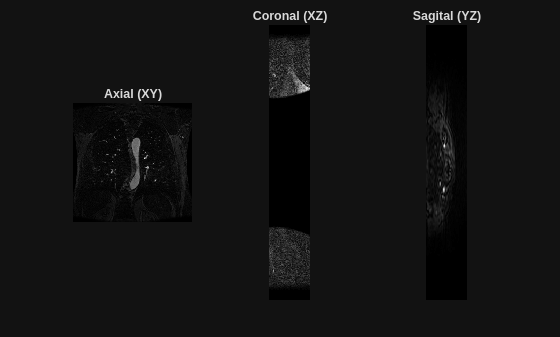


figure;

% Vista axial (XY)
subplot(1,3,1);
imshow(squeeze(X(:,:,sliceZ)), []);
title('Axial (XY)');

% Vista coronal (XZ)
subplot(1,3,2);
imshow(squeeze(X(:,sliceY,:)), []);
title('Coronal (XZ)');

% Vista sagital (YZ)
subplot(1,3,3);
imshow(squeeze(X(sliceX,:,:)), []);
title('Sagital (YZ)');

maxGlobal = max(X(:));
minGlobal = min(X(:));

% Mostrar resultados
disp(['Máximo global del stack: ', num2str(maxGlobal)]);

Máximo global del stack: 46336


disp(['Mínimo global del stack: ', num2str(minGlobal)]);

Mínimo global del stack: 0
